**LEP 6-2 : Membrane Reactor**

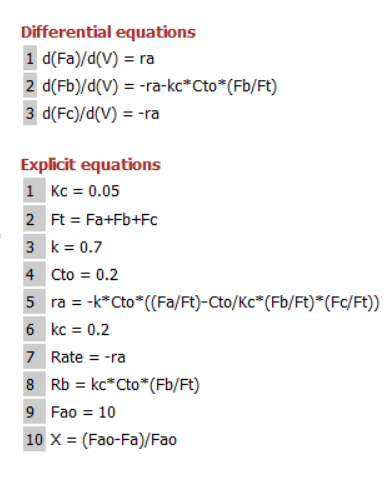

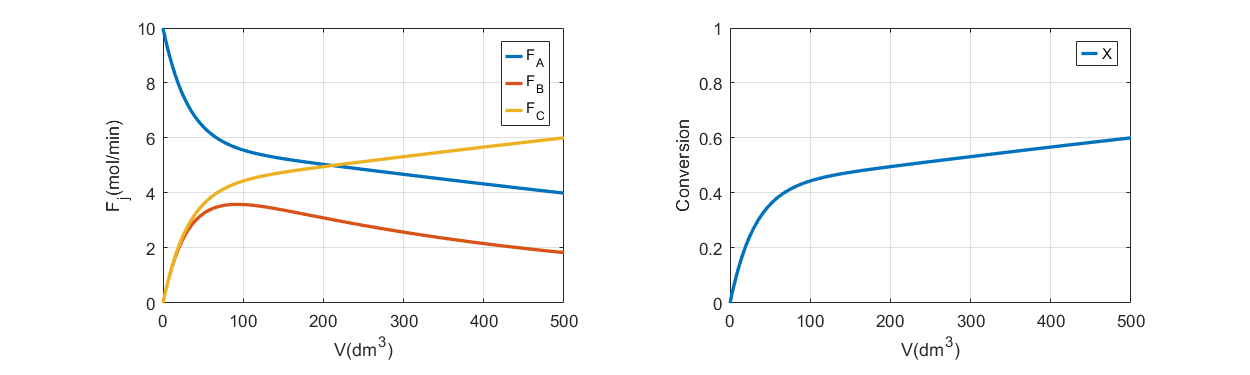

Vspan = [0 500]; % 
y0 = [10; 0; 0]; % 
Kc = 0.05; 
k = 0.7; 
Cto = 0.2; 
kc = 0.2; 
[v y]=ode45(@(v,y)ODEfun(v,y,Kc,k,Cto,kc),Vspan,y0);
tiledlayout(1,2)
set (gcf,'Position',[0,0.1,1000,300])
nexttile
plot(v,y(:,1),v,y(:,2),v,y(:,3),'LineWidth',2);
ylabel('F_j(mol/min)');
xlabel('V(dm^3)');
axis([0 500  0 10])
leg=legend('F_A','F_B','F_C');
leg.ItemTokenSize=[10,10];
grid on
% Part c
FAo=10;
z=size(y);
for i=1 : z(1,1)
X(i)=(FAo-y(i,1))/FAo;
end
nexttile
plot(v,X(1:z(1,1)),'LineWidth',2);
ylabel('Conversion');
xlabel('V(dm^3)');
axis([0 500  0 1])
leg=legend('X');
leg.ItemTokenSize=[10,10];
grid on

function dYfuncvecdV = ODEfun(V,Yfuncvec,Kc,k,Cto,kc); 
Fa = Yfuncvec(1); 
Fb = Yfuncvec(2); 
Fc = Yfuncvec(3); 
% Explicit equations
Ft = Fa + Fb + Fc; 
ra = 0 - (k * Cto * (Fa / Ft - (Cto / Kc * Fb / Ft * Fc / Ft))); 
% Differential equations
dFadV = ra; 
dFbdV = 0 - ra - (kc * Cto * Fb / Ft); 
dFcdV = 0 - ra; 
dYfuncvecdV = [dFadV; dFbdV; dFcdV]; 
end